close all; clc; clear all;

## Time span

tStart = 0;
tEnd = 20;
timeSpan = [tStart tEnd];

## Defining variables

global Kd Kp c v0 goal dMin

Kd = 1;
Kp = 10;
c = 1;
v0 = 0.2;
goal = [.5;-1];
dMin = 0.005;

## Initial conditions

initPhi = pi/4;
initPos = [0;0];
initR = 0;
z=[initPos;initPhi;initR];

## Solving ODE

[t,out] = ode45(@dinModel,timeSpan,z);

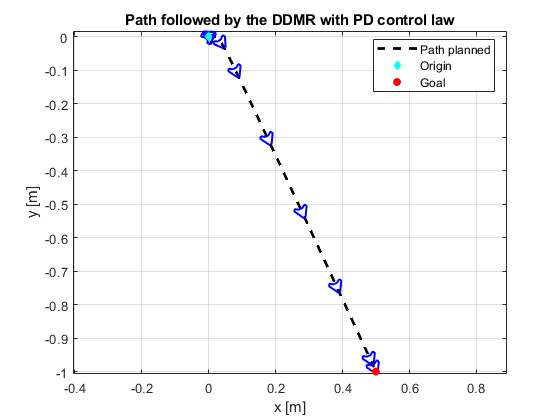

figure();
h(1) = plot(out(:,1),out(:,2),'k--','LineWidth',2); grid, hold on;
axis equal
xlabel("x [m]");
ylabel("y [m]");
title("Path followed by the DDMR with PD control law");
for i=1:round(size(out,1)/20):size(out,1)
    drawRobot(out(i,1),out(i,2),out(i,3),0.02,'b-');
end
h(2) = scatter(initPos(1),initPos(2),'filled',"dc");
h(3) = scatter(goal(1),goal(2),'filled',"or");
legend(h([1 2 3]),"Path planned","Origin","Goal",'Location','best')

## Functions

function zDot = dinModel(t,z)
    global Kd Kp c v0 goal dMin
        
    xDot = v0*cos(z(3));
    yDot = v0*sin(z(3));
    phiRef = atan2((goal(2)-z(2)),(goal(1)-z(1)));
    e = phiRef - z(3);
    phiDot = -Kd*c^2*z(4)+(Kp+Kd*c)*e;
    rDot = -c*z(4)+e;
    
    d = sqrt((goal(2)-z(2))^2+(goal(1)-z(1))^2);
    
    if(d < dMin)
        v0 = 0;
    end
     
    zDot = [xDot;yDot;phiDot;rDot];
end